# PCA & LDA

%% Data Input ---------------------------------------------------
% mat = xlsread('KO_RS_Cntnap2KO_31_MB.xlsx');
% Label = readcell('KO_lable_Cntnap2KO_31_MB.xlsx');

% mat = xlsread('KO_RS_Shank3KO_25_MB.xlsx');
% Label = readcell('KO_lable_Shank3KO_25_MB.xlsx');

mat = xlsread('KO_RS_total.xlsx');
Label = readcell('KO_lable_total.xlsx');

% mat = xlsread('WT_RS.xlsx');
% Label = readcell('WT_lable.xlsx');

% mat = xlsread('RS_values.xlsx');
% Label = readcell('LDAlabel1.xlsx');

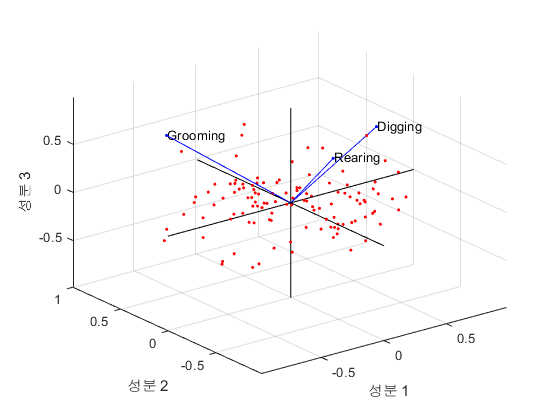

%% Principle Componenet Analysis --------------------------------
[coeff, score, latent, explained] = pca(mat);
biplot(coeff(:,1:3),'scores',score(:,1:3),'varlabels',{'Digging', ...
    'Grooming','Rearing'})
axis tight

%% Table array --------------------------------------------------
Analysis = [mat(:,1); mat(:,2); mat(:,3)];
Score = [score(:,1) ; score(:,2); score(:,3)];
LDA_Analysis = [table(Analysis) table(Score) Label];
Group1 = table2array(LDA_Analysis(:,1));
Group2 = table2array(LDA_Analysis(:,2));
Group3 = table2array(LDA_Analysis(:,3));

## Linear & Quadratic Discriminant Analysis

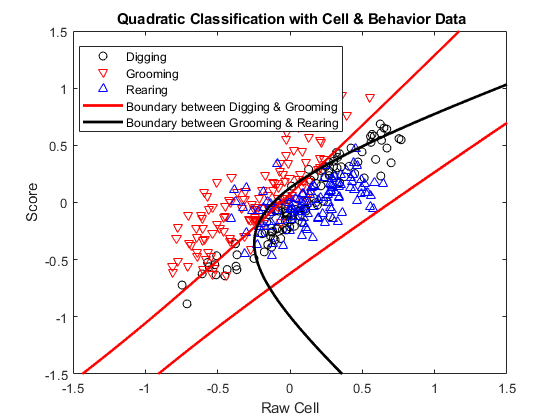

MdlQuadratic = fitcdiscr(LDA_Analysis(:,1:2),Label,...
    'DiscrimType','quadratic');
%% Scatter ------------------------------------------------------
h1 = gscatter(Group1,Group2,Group3,'krb','ov^',[],'off');
legend('Digging','Grooming','Rearing','Location','best')
hold on
%% Digging & Grooming -------------------------------------------
K = MdlQuadratic.Coeffs(1,2).Const;
L = MdlQuadratic.Coeffs(1,2).Linear; 
Q = MdlQuadratic.Coeffs(1,2).Quadratic;
f = @(x1,x2) K + L(1)*x1 + L(2)*x2 + Q(1,1)*x1.^2 + ...
    (Q(1,2)+Q(2,1))*x1.*x2 + Q(2,2)*x2.^2;
h2 = fimplicit(f,[-2 2 -2 2]); % Plot the relevant portion of the curve.
h2.Color = 'r';
h2.LineWidth = 2;
h2.DisplayName = 'Boundary between Digging & Grooming';
hold on
%% Rearing & Grooming -------------------------------------------
K = MdlQuadratic.Coeffs(2,3).Const;
L = MdlQuadratic.Coeffs(2,3).Linear; 
Q = MdlQuadratic.Coeffs(2,3).Quadratic;
f = @(x1,x2) K + L(1)*x1 + L(2)*x2 + Q(1,1)*x1.^2 + ...
    (Q(1,2)+Q(2,1))*x1.*x2 + Q(2,2)*x2.^2; 
h3 = fimplicit(f,[-2 2 -2 2]); % Plot the relevant portion of the curve.
h3.Color = 'k';
h3.LineWidth = 2;
h3.DisplayName = 'Boundary between Grooming & Rearing';
axis([-1.5 1.5 -1.5 1.5]);
xlabel('Raw Cell')
ylabel('Score')
title('{\bf Quadratic Classification with Cell & Behavior Data}')
hold off

## ABS score

abs_score = abs(Score);
LDA_Analysis = [table(Analysis) table(abs_score) Label];
Group1 = table2array(LDA_Analysis(:,1));
Group2 = table2array(LDA_Analysis(:,2));
Group3 = table2array(LDA_Analysis(:,3));

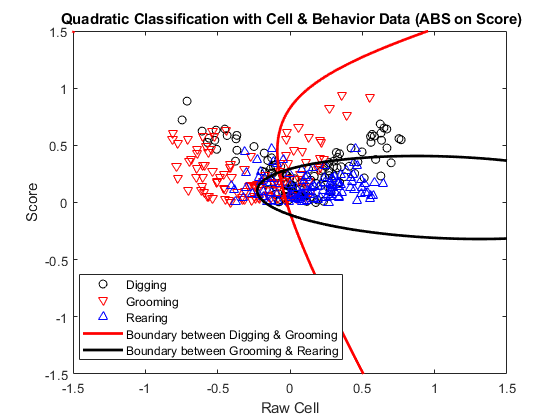

MdlQuadratic = fitcdiscr(LDA_Analysis(:,1:2),Label,...
    'DiscrimType','quadratic');
%% Scatter ------------------------------------------------------
h1 = gscatter(Group1,Group2,Group3,'krb','ov^',[],'off');
legend('Digging','Grooming','Rearing','Location','best')
hold on
%% Digging & Grooming -------------------------------------------
K = MdlQuadratic.Coeffs(1,2).Const;
L = MdlQuadratic.Coeffs(1,2).Linear; 
Q = MdlQuadratic.Coeffs(1,2).Quadratic;
f = @(x1,x2) K + L(1)*x1 + L(2)*x2 + Q(1,1)*x1.^2 + ...
    (Q(1,2)+Q(2,1))*x1.*x2 + Q(2,2)*x2.^2;
h2 = fimplicit(f,[-2 2 -2 2]); % Plot the relevant portion of the curve.
h2.Color = 'r';
h2.LineWidth = 2;
h2.DisplayName = 'Boundary between Digging & Grooming';
hold on
%% Rearing & Grooming -------------------------------------------
K = MdlQuadratic.Coeffs(2,3).Const;
L = MdlQuadratic.Coeffs(2,3).Linear; 
Q = MdlQuadratic.Coeffs(2,3).Quadratic;
f = @(x1,x2) K + L(1)*x1 + L(2)*x2 + Q(1,1)*x1.^2 + ...
    (Q(1,2)+Q(2,1))*x1.*x2 + Q(2,2)*x2.^2; 
h3 = fimplicit(f,[-2 2 -2 2]); % Plot the relevant portion of the curve.
h3.Color = 'k';
h3.LineWidth = 2;
h3.DisplayName = 'Boundary between Grooming & Rearing';
axis([-1.5 1.5 -1.5 1.5]);
xlabel('Raw Cell')
ylabel('Score')
title('{\bf Quadratic Classification with Cell & Behavior Data (ABS on Score)}')
hold off